%Расчёт параметров для каждого цикла:
% Амплитуда реограммы и время максимума
for i = 1:length(CYCLE_DATA)
    Amp = max(-CYCLE_DATA{i}.RHEO2) - min(-CYCLE_DATA{i}.RHEO2);
end

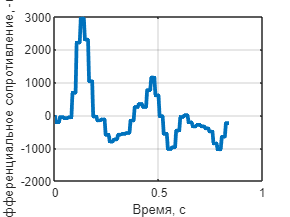

        % Данные дифференциальной реограммы
        i = 100;
        dRHEO1{i}(1) = 0;
        dRHEO2{i}(1) = 0;
        for j=2:length(CYCLE_DATA{i}.TIME)
            dRHEO1{i}(j) = (CYCLE_DATA{i}.RHEO1(j) - CYCLE_DATA{i}.RHEO1(j-1))*10^(-3)/0.005; %В Ом/с
            dRHEO2{i}(j) = (CYCLE_DATA{i}.RHEO2(j) - CYCLE_DATA{i}.RHEO2(j-1))*10^(-3)/0.005; %В Ом/с
        end
        
        % Амплитуда дифференциальной реограммы и время 
        [d_Amp1(i),idx_t_dAmp] = max(dRHEO1{i});
        t_dAmp1(i) = (idx_t_dAmp-1)*0.005;

        [d_Amp2(i),idx] = max(dRHEO2{i});
        t_dAmp2(i) = (idx-1)*0.005;
plot(CYCLE_DATA{i}.TIME,-dRHEO1{i}*1000,'LineWidth',3)
ylabel("Дифференциальное сопротивление, -мОм/c");
xlabel("Время, с");
grid on

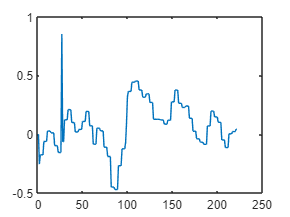

% Амплитуда дифференциальной реограммы и время 


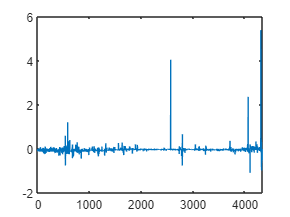

% Период изгнания и значение в этой точке (для больших отведений)

[Amp1,t_Amp1,Amp2,t_Amp2,d_Amp1,t_dAmp1,d_Amp2,t_dAmp2,dRHEO1,Tlvet,Z_Tlvet,dZ,dV] = params_new(CYCLE_DATA);
plot(dV)

% Длительность кардиоцикла
[~,idx] = max(CYCLE_DATA{1}.RHEO1);

test_t = CYCLE_DATA{20}.TIME;
test_data = -CYCLE_DATA{20}.RHEO2;

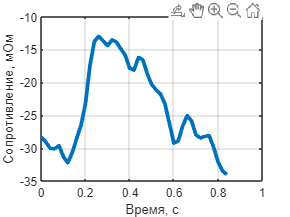

% Приведение к одной линии
time = [CYCLE_DATA{100}.TIME(1);CYCLE_DATA{100}.TIME(end)];
value = -[CYCLE_DATA{1000}.RHEO2(1);CYCLE_DATA{100}.RHEO2(end)];
coefs = coeffvalues(fit(time,value,'poly1'));
CYCLE_NEW = -CYCLE_DATA{100}.RHEO2-(coefs(1)*CYCLE_DATA{100}.TIME);
%plot(CYCLE_DATA{100}.TIME,CYCLE_NEW,CYCLE_DATA{100}.TIME,-CYCLE_DATA{100}.RHEO2,'LineWidth',3)
%legend(["После выравнивания" "До выравнивания"]);
plot(CYCLE_DATA{100}.TIME,CYCLE_NEW,'LineWidth',3)
ylabel("Сопротивление, мОм");
xlabel("Время, с");
grid on

function [Amp1,t_Amp1,Amp2,t_Amp2,d_Amp1,t_dAmp1,d_Amp2,t_dAmp2,dRHEO1,Tlvet,Z_Tlvet,T,dZ,dV] = params_new(DATA)
    for i = 1:length(DATA)
        DATA{i}.RHEO1 = - DATA{i}.RHEO1;
        DATA{i}.RHEO2 = - DATA{i}.RHEO2;

        % Приведение к одной линии
        time1 = [DATA{i}.TIME(1);DATA{i}.TIME(end)];
        value1 = [DATA{i}.RHEO1(1);DATA{i}.RHEO1(end)];
        coefs1 = coeffvalues(fit(time1,value1,'poly1'));
        DATA_TEMP1 = DATA{i}.RHEO1;
        DATA{i}.RHEO1 = DATA_TEMP1 - coefs1(1)*DATA{i}.TIME;
        
        time2 = [DATA{i}.TIME(1);DATA{i}.TIME(end)];
        value2 = [DATA{i}.RHEO2(1);DATA{i}.RHEO2(end)];
        coefs2 = coeffvalues(fit(time2,value2,'poly1'));
        DATA_TEMP2 = DATA{i}.RHEO2;
        DATA{i}.RHEO2 = DATA_TEMP2 - coefs2(1)*DATA{i}.TIME;


        % Амплитуда реограммы и время максимума
        Amp1(i) = (max(DATA{i}.RHEO1) - min(DATA{i}.RHEO1))*10^(-3);%В омах
        [~,id1_max] = max(DATA{i}.RHEO1);
        t_Amp1(i) = (id1_max-1)*0.005;

        Amp2(i) = (max(DATA{i}.RHEO2) - min(DATA{i}.RHEO2))*10^(-3);%В омах
        [~,id2_max] = max(DATA{i}.RHEO2);
        t_Amp2(i) = (id2_max-1)*0.005;

        % Данные дифференциальной реограммы
        dRHEO1{i}(1) = 0;
        dRHEO2{i}(1) = 0;
        for j=2:length(DATA{i}.TIME)
            dRHEO1{i}(j) = (DATA{i}.RHEO1(j) - DATA{i}.RHEO1(j-1))*10^(-3)/0.005; %В Ом/с
            dRHEO2{i}(j) = (DATA{i}.RHEO2(j) - DATA{i}.RHEO2(j-1))*10^(-3)/0.005; %В Ом/с
        end
        
        % Амплитуда дифференциальной реограммы и время 
        [d_Amp1(i),idx_t_dAmp] = max(dRHEO1{i});
        t_dAmp1(i) = (idx_t_dAmp-1)*0.005;

        [d_Amp2(i),idx] = max(dRHEO2{i});
        t_dAmp2(i) = (idx-1)*0.005;


        % Период изгнания и значение в этой точке (для больших отведений)
        [~,idx_min] = min(dRHEO1{i}(1:floor(length(DATA{i}.RHEO1)*2/3)));

        Tlvet(i) = (idx_min-1)*0.005 - t_dAmp1(i);
        Z_Tlvet(i) = DATA{i}.RHEO1(idx_min);
        T(i) = (length(DATA{i}.RHEO1)-1)*0.005;

        %искомое дельта зед
        idx_dZ = idx_min;
        res = coeffvalues(fit(DATA{i}.TIME(end-idx_dZ:end),DATA{i}.RHEO2(end-idx_dZ:end)/1000,'poly1'));
        coeff(i) = res(1); 
        dZ(i) = coeff(i)*T(i);
        k = 24;
        HR = 1/T(i)*60;
        dV(i)=0.1*1.35*10^6*dZ(i)/k*HR/(mean(DATA{i}.BASE2)/k*975*(dZ(i)/k - mean(DATA{i}.BASE2)/k));
    
    end
end
